close all; 
clear *;
clc;
% Sampling frequency in <Hz>
fs = 1;
% Cutoff frequency in <Hz>
fc = 0.1;
% Filter order
N = 30;
% Design filter (floating-point)
h = fir1(N, fc/(fs/2), 'low', hamming(N+1));

L = 2048;
H = fft(h,L);
f = (0:L-1)/L*2;
H = H(1:L/2);
f = f(1:L/2);


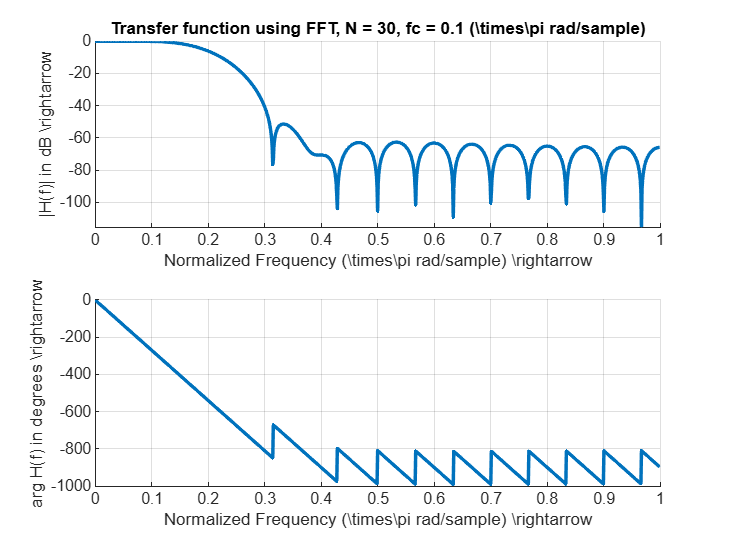


% Plot frequency response (magnitude in dB)
figure(1);
subplot(211);
plot(f, 20*log10(abs(H)), 'LineWidth', 2); grid on; hold on; box off;
xlabel('Normalized Frequency (\times\pi rad/sample) \rightarrow'); 
ylabel('|H(f)| in dB \rightarrow');
title(['Transfer function using FFT, N = ' num2str(N) ', fc = ' num2str(fc) ' (\times\pi rad/sample)']);

% Plot phase response
subplot(212);
plot(f, unwrap(angle(H)) * 180/pi, 'LineWidth', 2); grid on; hold on; box off;
xlabel('Normalized Frequency (\times\pi rad/sample) \rightarrow'); 
ylabel('arg H(f) in degrees \rightarrow');

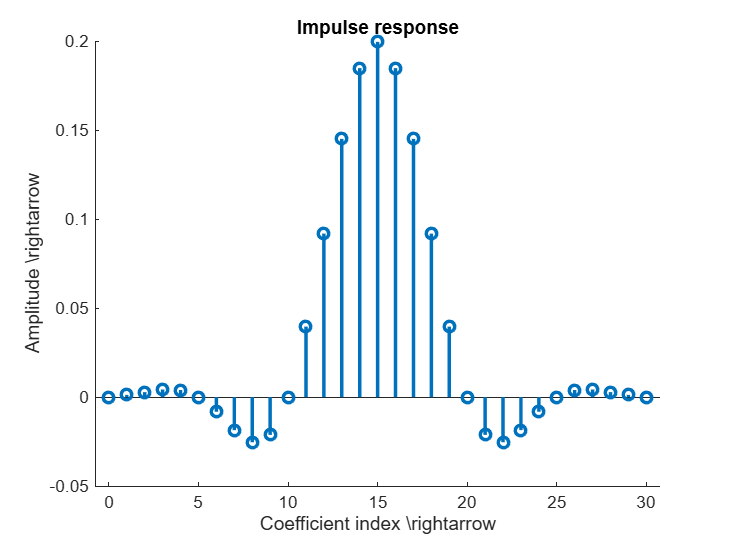


% Plot impulse response
figure(2);
stem(0:N, h, 'LineWidth', 2); hold on; box off;
xlabel('Coefficient index \rightarrow'); ylabel('Amplitude \rightarrow');
title('Impulse response');